dataset= readtable('/Users/lynnxt/Desktop/LOB_data.csv');
dataset

dataset = 621×3 table
    SourceTime    bid_price    ask_price
    __________    _________    _________

         1         134.36       135.36  
         2         149.34       150.34  
         3         141.75       142.75  
         4         141.75       142.75  
         5         141.58       142.58  
         6         142.07       143.07  
         7         119.02       120.02  
         8          130.1        131.1  
         9         134.62       135.62  
        10         136.67       137.67  
        11         139.39       140.39  
        12         140.11       141.11  
        13         140.41       141.41  
        14         141.37       142.37  
        15          141.4        142.4  
        16         141.91       142.91  



% mid_price
dataset.mid_price = (dataset.ask_price + dataset.bid_price) / 2;

windowSize = 10; 
numFeatures = 2 * windowSize; 
numObservations = height(dataset) - windowSize;
features = zeros(numObservations, numFeatures);
labels = zeros(numObservations, 1);

for i = 1:numObservations
    
    askPrices = dataset.ask_price(i:i+windowSize-1);
    bidPrices = dataset.bid_price(i:i+windowSize-1);
    
    
    features(i, :) = [askPrices', bidPrices'];
    
   
    labels(i) = dataset.mid_price(i + windowSize);
end

cv = cvpartition(numObservations, 'HoldOut', 0.2);
X_train = features(cv.training, :);
Y_train = labels(cv.training);
X_test = features(cv.test, :);
Y_test = labels(cv.test);

% regression model
rfModel = TreeBagger(50, X_train, Y_train, 'Method', 'regression');

%test
[Y_pred, scores] = predict(rfModel, X_test);

% MSE
mse = mean((Y_test - Y_pred).^2);
fprintf('Mean Squared Error: %.4f\n', mse);

Mean Squared Error: 2.1485


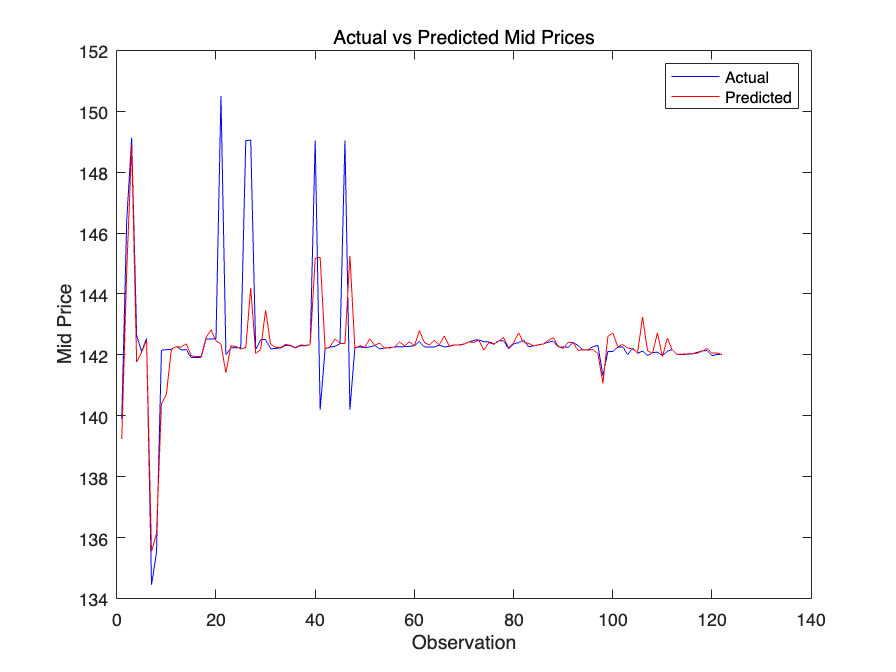


% visualization
figure;
plot(Y_test, 'b');
hold on;
plot(Y_pred, 'r');
legend('Actual', 'Predicted');
xlabel('Observation');
ylabel('Mid Price');
title('Actual vs Predicted Mid Prices');